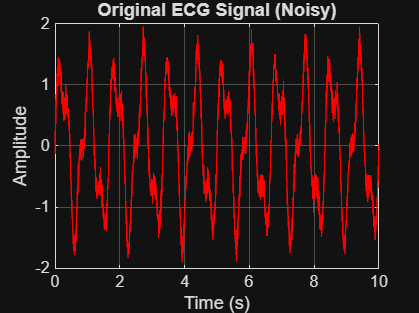

%% ECG Signal Filtering and Analysis (Full Script)
% Authors: Vinay Katkar, Karna Jadhav, Shrey Gundecha
% Guide: Dr. Shanti Syami, SPIT

clc; clear; close all;

% -------------------------
% Parameters
% -------------------------
fs = 360;                % sampling frequency (Hz)
duration = 10;           % seconds
t = 0:1/fs:duration;     % time vector

% -------------------------
% Load ECG or Generate Synthetic (uncomment one)
% -------------------------
% Option A: Load if you have ecg.mat and variable 'ecg' inside:
% try
%    load('ecg.mat');  % ensure ecg variable exists
% catch
%    warning('ecg.mat not found. Using synthetic ECG.');
%    ecg = [];
% end
%
% Option B: If ecg variable not found, generate synthetic ECG-like signal:
ecg = 1.2*sin(2*pi*1.2*t) + 0.5*sin(2*pi*3*t) + 0.1*randn(size(t));
% (This produces an ECG-like waveform for demo purposes.)

% -------------------------
% Plot Original ECG
% -------------------------
figure('Name','Original ECG');
plot(t, ecg, 'r');
xlabel('Time (s)'); ylabel('Amplitude');
title('Original ECG Signal (Noisy)');
grid on;

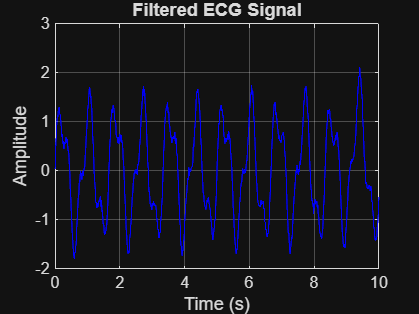


% -------------------------
% Filter Design
% -------------------------
% High-pass filter to remove baseline wander (<0.5 Hz)
hpFilt = designfilt('highpassiir','FilterOrder',4, ...
         'HalfPowerFrequency',0.5,'SampleRate',fs);

% Low-pass filter to remove muscle noise (>40 Hz)
lpFilt = designfilt('lowpassiir','FilterOrder',4, ...
         'HalfPowerFrequency',40,'SampleRate',fs);

% Notch filter for powerline interference (50 Hz)
wo = 50/(fs/2); bw = wo/35;  % adjust bw for notch sharpness
[b_notch, a_notch] = iirnotch(wo, bw);

% -------------------------
% Apply Filters (zero-phase)
% -------------------------
ecg_hp = filtfilt(hpFilt, ecg);
ecg_lp = filtfilt(lpFilt, ecg_hp);
ecg_clean = filtfilt(b_notch, a_notch, ecg_lp);

% -------------------------
% Plot Filtered ECG
% -------------------------
figure('Name','Filtered ECG');
plot(t, ecg_clean, 'b');
xlabel('Time (s)'); ylabel('Amplitude');
title('Filtered ECG Signal');
grid on;


% -------------------------
% QRS Detection using findpeaks
% -------------------------
minPeakHeight = 0.6 * max(ecg_clean);  % adjust threshold as needed
minPeakDistance = 0.25 * fs;          % 250 ms between peaks (approx)

[pks, locs] = findpeaks(ecg_clean, 'MinPeakHeight', minPeakHeight, ...
                        'MinPeakDistance', minPeakDistance);

% Convert locs (indices) to time
locs_time = (locs-1) / fs;

% -------------------------
% Heart Rate Calculation
% -------------------------
RR_intervals = diff(locs_time);           % seconds
if isempty(RR_intervals)
    warning('No RR intervals detected. Adjust detection parameters.');
    avg_HR = NaN;
else
    heart_rate_inst = 60 ./ RR_intervals;   % instantaneous bpm
    avg_HR = mean(heart_rate_inst);         % average bpm
end

% Print results
fprintf('Detected Peaks: %d\n', length(locs));

Detected Peaks: 11


fprintf('Average Heart Rate = %.2f bpm\n', avg_HR);

Average Heart Rate = 68.48 bpm


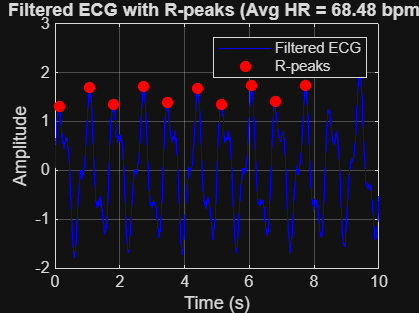


% -------------------------
% Plot ECG with detected R-peaks
% -------------------------
figure('Name','ECG with R-peaks');
plot(t, ecg_clean, 'b'); hold on;
plot(locs_time, pks, 'ro', 'MarkerFaceColor','r');
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('Filtered ECG with R-peaks (Avg HR = %.2f bpm)', avg_HR));
legend('Filtered ECG', 'R-peaks');
grid on;


% -------------------------
% End of script
% -------------------------


